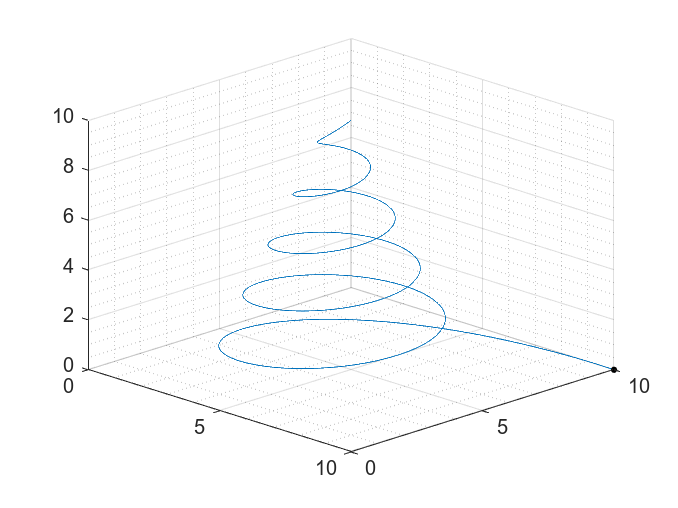

%clear
%animation speed should be pmax*pstep/20fps???? Changed between 1 and 2
%stack, need to fix this, get animations up to 4 stack, and redo NBR with
%lower sample rate to fit animation to 1000 frames
%ALL ANIMATIONS SHOULD FIT 1000 FRAMES FOR EXPORT
%----------------------
%3D <-> 2D CHANGES
%third dimensional vector added for each derivative
clear subplot
sz = size(PosMAT);
len = sz(1,1);
%pos
x = PosMAT(:,1);
y = PosMAT(:,2);
z = PosMAT(:,3);
%vel
u = VelMAT(:,1);
v = VelMAT(:,2);
w = VelMAT(:,3);
%acc
a = AccMAT(:,1);
b = AccMAT(:,2);
c = AccMAT(:,3);
%jerk
j = JerkMAT(:,1);
k = JerkMAT(:,2);
l = JerkMAT(:,3);
%snap
s = SnapMAT(:,1);
t = SnapMAT(:,2);
r = SnapMAT(:,3);
%subplot(2,1,1);
plts = cell(1,11);
plts{1,1} = plot3(x,y,z);
hold on
grid on
grid minor
view([45, 25]);
plts{1,2} = quiver3(x(1), y(1), z(1), u(1), v(1), w(1), 'off', 'green');
plts{1,3} = quiver3(x(1), y(1), z(1), a(1), b(1), c(1), 'off', 'red');
plts{1,4} = quiver3(x(1), y(1), z(1), j(1), k(1), l(1), 'off', 'blue');
plts{1,5} = quiver3(x(1), y(1), z(1), s(1), t(1), r(1), 'off', 'black');
plts{1,10} = scatter(x(1), y(1), z(1), "o", 'filled', 'black');
%plts{1,11} = plot3([x(1),x(1)], [y(1),y(1)], [0,10]);
hold off
%subplot(2,1,2);
for i = 1:1:len
    %Update graph values
    set(plts{1,2},'XData', x(i), 'YData', y(i), 'ZData', z(i), 'UData', u(i), 'VData', v(i), 'WData', w(i));
    set(plts{1,3},'XData', x(i), 'YData', y(i), 'ZData', z(i), 'UData', a(i), 'VData', b(i), 'WData', c(i));
    set(plts{1,4},'XData', x(i), 'YData', y(i), 'ZData', z(i), 'UData', j(i), 'VData', k(i), 'WData', l(i));
    set(plts{1,5},'XData', x(i), 'YData', y(i), 'ZData', z(i), 'UData', s(i), 'VData', t(i), 'WData', r(i));
    set(plts{1,10},'XData', x(i), 'YData', y(i), 'ZData', z(i));
%    set(plts{1,11},'XData', [x(i),x(i)], 'YData', [y(i),y(i)]);
    %Draw updated graph
    drawnow limitrate;
end

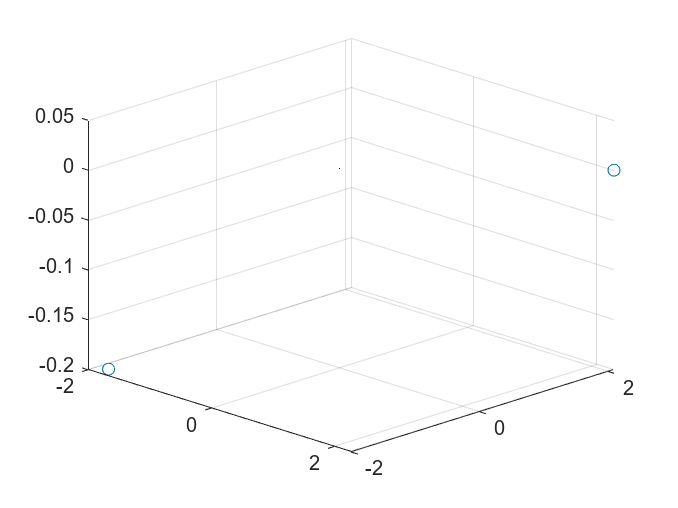

scatter3([max(u,[],"all"); min(u,[],"all")], [max(v,[],"all"); min(v,[],"all")], [-max(w,[],"all"); min(w,[],"all")]);
hold on
view([45, 25]);
plts{1,6} = quiver3(0, 0, 0, u(1), v(1), w(1), 'off', 'green');
plts{1,7} = quiver3(0, 0, 0, a(1), b(1), c(1), 'off', 'red');
plts{1,8} = quiver3(0, 0, 0, j(1), k(1), l(1), 'off', 'blue');
plts{1,9} = quiver3(0, 0, 0, s(1), t(1), r(1), 'off', 'black');
hold off
for i = 1:1:len
    set(plts{1,6},'XData', 0, 'YData', 0, 'ZData', 0, 'UData', u(i), 'VData', v(i), 'WData', w(i));
    set(plts{1,7},'XData', 0, 'YData', 0, 'ZData', 0, 'UData', a(i), 'VData', b(i), 'WData', c(i));
    set(plts{1,8},'XData', 0, 'YData', 0, 'ZData', 0, 'UData', j(i), 'VData', k(i), 'WData', l(i));
    set(plts{1,9},'XData', 0, 'YData', 0, 'ZData', 0, 'UData', s(i), 'VData', t(i), 'WData', r(i));
    drawnow limitrate;
end